# Práctica 1: Resolución numérica de EDO,s.

Equipo: Miguel Egido, Alfredo Robledano

### **Primera pregunta.**

Crea un código que dada un función $f:$[a,b]$\longrightarrow \mathbb{R}$, un número natural $$n\geq 1$$ y un número  $$i=0,... ,n-1$$,devuelva una cota superior del error local del truncamiento en el paso $$i$$-ésimo.

Ayuda: Recuerda que el error local de truncamiento en el paso $$i$$-ésimo es el correspodiente al subintervalo [$\left.t_i ,t_{i+1} \right\rbrack \ldotp$ Trata también el caso cuando $i\geq n$ ya que no aplica en este caso devolviendo un mensaje con el error correspondiente. (Trata la variable $x$ de $f$ como simbólica).

#### **Solución primera pregunta:**

Una vez definido el PVI se calcula su solución para calcular la solución exacta del PIV. Para calcular el error local de truncamiento, comparamos la solución exacta del PVI con la solución obtenida utilizando el método numérico.

Después de calcular la segunda derivada de la solución exacta del problema de valor inicial (PVI) y determinar el tamaño del paso h para la discretización del intervalo [a,b], el código procede a calcular la derivada segunda de la solución exacta, x''(t), en los puntos críticos candidatos. Estos puntos críticos se encuentran buscando las raíces de la primera derivada de x''(t).

Evaluamos x''(t) en los extremos de los intervalos consecutivos de tamaño h. También se evalúa x''(t) en los puntos críticos candidatos y en los extremos de ambos intervalos almacenandolos en el vector f target. 

Por último calculamos el error local de truncamiento: $e_i =\frac{1}{2}\max |{x^{\prime } }^{\prime } \left(c\right){|\;h}^2$

**Codigo:**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

a = 0;
b = 2;
n = 10;
i = 1;

syms x(t) t
d1x = diff(x, t, 1);
ode = d1x == x + t

$$ode(t) = \frac{\partial }{\partial t}x\left(t\right)=t+x\left(t\right)$$

cond = x(0) == 1

$$cond = x\left(0\right)=1$$

xsol = dsolve(ode, cond)

$$xsol = 2\,{\mathrm{e}}^{t}-t-1$$


if i == 0
    disp('El error local de truncamiento para 0 pasos es cero')
elseif i >= n
    disp('El paso i-ésimo debe estar entre 0 y n-1')
else
    h = (b-a)/n
    
    d2x = diff(d1x, t, 1)
    d2xsol = subs(d2x, x, xsol)
    
    f_target = abs(d2xsol); % f_target = |x''| siendo x la solución real
    d1f_target = diff(f_target, t, 1);
    f_target_candidatos = double(solve(d1f_target == 0));
    
    t_anterior = h*(i-1);
    t_siguiente = h*i;
    
    f_target_anterior = double(subs(f_target, t, t_anterior));
    f_target_siguiente = double(subs(f_target, t, t_siguiente));
    
    f_target_extremos = double(subs(f_target, t, [t_anterior, t_siguiente]));
    f_target = [f_target_candidatos, f_target_extremos];
    
    ei = 1/2 * max(f_target) * h^2;
    fprintf('Error local de truncamiento paso %d-ésimo:\n|ei|<=%.4f',i, ei)
end

h = 0.2000

$$d2x(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

$$d2xsol(t) = 2\,{\mathrm{e}}^{t}$$

Error local de truncamiento paso 1-ésimo:
|ei|<=0.0489

### Segunda pregunta.

Sea el PVI  $$$
\left\{\begin{array}{l}x'=\ln(t^2)x\\
x(1)=1
\end{array}
\right.
$$$ , donde $f:[1,2]\times\mathbb R\longrightarrow  \mathbb{R}$ está dada por 

$f(t,x) = \ln(t^2)x$.

Tratanto a $f(t,x)$ como una función anónima, implementa un código que devuelva una **ÚNICA** gráfica con la solución aproximada del PVI por el método de Euler mejorado, tomando $n=10,25, 50$ y $100$, siendo $n$ el número de pasos de la partición del  intervalo. Para cada $n$ asigna a la solución aproximada correspondiente colores distintos y asignales una leyenda para distinguirlos en la gráfica.

#### Solución segunda pregunta:

Comenta brevemente si la solución del PVI está globalmente definida en el intervalo (usa los símbolos matemáticos en la pestaña de INSERT si fuera necesario).

**Comentario:**

syms x(t)
f = log(t^2)*x

$$f(t) = \log\left(t^{2}\right)\,x\left(t\right)$$


$$f\left(x,t\right)=\log \left(t^2 \right)\;x$$
 

df_dx = diff(f, x, 1)

$$df\_dx(t) = \log\left(t^{2}\right)$$


$$\frac{\partial }{\partial x}f\left(x,t\right)=\;\log \left(t^2 \right)$$


Por ser $f\left(x,t\right)=\log \left(t^2 \right)\;x$  $\frac{\partial }{\partial x}f\left(x,t\right)=\;\log \left(t^2 \right)$ continuas y acotadas en un réctangulo que contiene a (1, 1) existe solución del PVI en un entorno de t=1.

El Teorema global de Cauchy-Lipschitz no garantiza la existencia de solución global única.

Podemos echar un vistado al resultado que da matlab:

ode = diff(x, t, 1) == f

$$ode(t) = \frac{\partial }{\partial t}x\left(t\right)=\log\left(t^{2}\right)\,x\left(t\right)$$

cond = x(1) == 1

$$cond = x\left(1\right)=1$$

sol = dsolve(ode, cond)

$$sol = {\mathrm{e}}^{2}\,{\mathrm{e}}^{2\,t\,\left(\log\left(t\right)-1\right)}$$

**Código:**

Al final de este pdf se implementa la función euler_mejorado

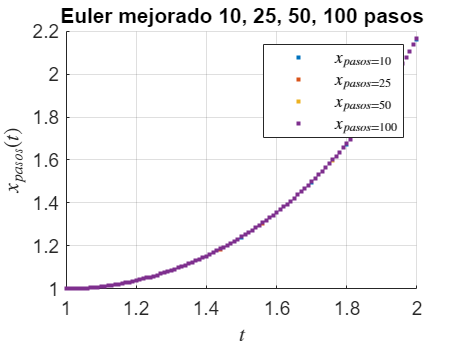

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

f = @(t, x) log(t^2).*x;

num_pasos = [10, 25, 50, 100];
x0 = 1;
a = 1;
b = 2;

hold on
for i=1:length(num_pasos)
    [x, t] = euler_mejorado(f, x0, a, b, num_pasos(i)); 
    scatter(t, x, '.',DisplayName=sprintf("$x_{pasos=%d}$", num_pasos(i)))
    xlabel('$t$', Interpreter='latex')
    ylabel('$x_{pasos}(t)$', Interpreter='latex')
end
grid on
legend('show', Interpreter='latex')
title('Euler mejorado 10, 25, 50, 100 pasos')
hold off

### Tercera pregunta.

Generaliza el código de la segunda pregunta para crear una función del tipo function cuyos inputs sean la función anónima $f$, los extremos del intervalo $[a,b]$ y el número de pasos deseado $n$. Y sus outputs sean una lista de la partición del intervalo y otra de sus respectivas aproximaciones por el método de Euler mejorado junto a su gráfica.

#### Solución tercera pregunta:

Generalizamos el código de la segunda pregunta con la función plot_euler_mejorado() que llama a euler_mejorado y hace plot además de devolver como salidas valores de las variables [x, t].

**Código:**

Al final de este pdf se implementa la función plot_euler_mejorado

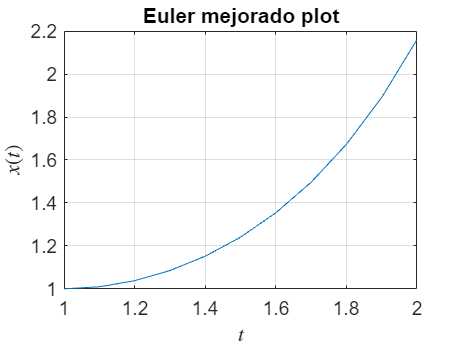

num_pasos = 10;
for i=1:length(num_pasos)
    [x, t] = plot_euler_mejorado(f, x0, a, b, num_pasos(i));
end

#### Funciones adicionales

function [x, t] = euler_mejorado(f, x0, a, b, n)
    h = (b-a)/n;
    x = zeros(1, n+1);
    x(1) = x0;
    t = a:h:b;
    for i=1:n
        k1 = f(t(i), x(i));
        k2 = f(t(i)+h, x(i)+h*k1);
        x(i+1) = x(i)+h/2*(k1+k2);
    end
end

function [x, t] = plot_euler_mejorado(f, x0, a, b, n)
    [x, t] = euler_mejorado(f, x0, a, b, n);
    plot(t, x)
    grid on
    legend(Interpreter='latex')
    xlabel('$t$', Interpreter='latex')
    ylabel('$x(t)$', Interpreter='latex')
    legend('hide')
    title('Euler mejorado plot')
end